# Copyright of this code belongs to Frank Lawless (flawless@uncc.edu).

Do not distribute this code.

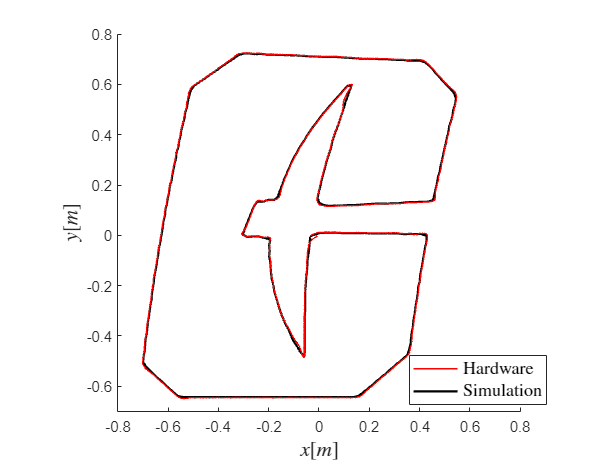

clear all 
close all

global d h k m;
% 'd' is the distance of the pen from the base of the robot
% 'k', 'm' are the control parameters
d = .0469; % base-point size of robot
k = 1; 
m = .1;

h = .08; 

% import reference trajectory and hardware results
position = importdata("logo.csv");
hardware = importdata("hardware_results.csv");

% scale reference trajectory to the hardware environment
position = position/1000*1.5;
position(2,:) = position(2,:)-1.5/2*.96;
position(1,:) = position(1,:)-1.5/2*1.1; 

T = size(position,2)-1;
t = 1:T;
figure
xVelocity = (position(1,t+1) - position(1,t))/h;
yVelocity = (position(2,t+1) - position(2,t))/h;
 
state(:,1) =[position(1,1)-d; position(2,1); 0];
xb(1) = state(1,1) + d*cos(state(3,1));
yb(1) = state(2,1) + d*sin(state(3,1));

theta(1) = state(3,1); 
theta_hat(1) = state(3,1);

for t = 1 : T
    % x= current state
    x = [xb(t); yb(t); theta(t)];

    % controller returns the desired velocities
    [v(t), w(t)] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
   
    % use the dynamics with desired velocities to generate the velocities
    dot_x = dynamics(theta(t),v(t),w(t));
     
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = theta(t) + dot_x(3)*h;
end

figure
hold on
h1(3) = plot(xb(:), yb(:),'color','k','DisplayName', 'Simulation','LineWidth',1.5);
h1(2) = plot(hardware(1,:), hardware(2,:),'color', 'r','LineWidth',1,'DisplayName','Hardware'); 

legend(h1([2, 3]),'location','best',Interpreter='latex',FontSize=12)
ylabel("$y [m]$",'interpreter', 'Latex', FontSize=14)
xlabel("$x [m]$",'interpreter', 'Latex',FontSize=14)
axis equal
ylim([-.7, .8])
xlim([-.8, .8])
hold off

function [v, w] = controller(x, xVelocity, yVelocity,position)
global d k m

J = [cos(x(3)) -d*sin(x(3));
    sin(x(3))  d*cos(x(3)) ];
E = x(1:2,1)- [position(1); position(2)];

if norm(E) > m && non_linear_control == 1
        v_feedback = [xVelocity; yVelocity] - k*m/norm(E)*E;
else
    v_feedback = [xVelocity; yVelocity] - k*E;
end

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(theta,v,w)
global d
M = [cos(theta) -d*sin(theta);
     sin(theta)  d*cos(theta);
     0               1      ];

dot_x = M*[v; w];
end